%% FORECAST FRANCE CO2 EMISSIONS TO 2050 USING ARIMA(5,0,5)
% This script uses the trained quadratic model to forecast emissions through 2050

%% SECTION 1 — Load the saved model and data
load('QuadraticModel_Results.mat');

fprintf('✅ Loaded saved model and data\n');

✅ Loaded saved model and data


fprintf('Model: ARIMA(5,0,5)\n');

Model: ARIMA(5,0,5)


fprintf('Training period: %s to 2023\n', datestr(trainData.Year(1)));

Training period: 01-Jan-1810 to 2023



%% SECTION 2 — Prepare forecast horizon to 2050
fprintf('\n===== PREPARING FORECAST TO 2050 =====\n');


===== PREPARING FORECAST TO 2050 =====



% Last year in training data (should be 2023)
lastYear = year(trainData.Year(end));
targetYear = 2050;

% Calculate how many years to forecast from the end of test data
yearsToForecast = targetYear - lastYear;
fprintf('Forecasting %d years ahead (from %d to %d)\n', yearsToForecast, lastYear, targetYear);

Forecasting 33 years ahead (from 2017 to 2050)



% Create future years
futureYears = (lastYear+1:targetYear)';
futureDates = datetime(futureYears, 1, 1);

%% SECTION 3 — Extend the quadratic trend to 2050
fprintf('\n===== EXTENDING QUADRATIC TREND =====\n');


===== EXTENDING QUADRATIC TREND =====



% Get the original time normalization parameters
t_train = year(trainData.Year);
t_min = min(t_train);
t_max = max(t_train);

% Create indices for future years (continuing from training data only)
futureIdx = (height(trainData) + 1 : height(trainData) + yearsToForecast)';

% Fit polynomial to training trend to get coefficients
t_train_idx = (1:height(trainData))';
p_coeffs = polyfit(t_train_idx, trendQuadratic, 2);

% Evaluate quadratic trend at future time points
futureTrendLog = polyval(p_coeffs, futureIdx);

fprintf('✅ Quadratic trend extended to 2050\n');

✅ Quadratic trend extended to 2050



%% SECTION 4 — Forecast ARIMA component
fprintf('\n===== FORECASTING ARIMA COMPONENT =====\n');


===== FORECASTING ARIMA COMPONENT =====



% Forecast the ARIMA model from the end of training data
horizonFuture = yearsToForecast;
[futureArimaFrcst, ~] = forecast(bestModel, horizonFuture, 'Y0', yDetrended);

fprintf('✅ ARIMA forecasts generated\n');

✅ ARIMA forecasts generated



%% SECTION 5 — Combine trend and ARIMA to get final predictions
fprintf('\n===== GENERATING FINAL PREDICTIONS =====\n');


===== GENERATING FINAL PREDICTIONS =====



% Combine trend + ARIMA forecast (in log scale)
futureLogPredictions = futureTrendLog + futureArimaFrcst;

% Convert back to original scale
futurePredictions = exp(futureLogPredictions) - 1;

% Create results table
forecastTable = table(futureDates, futureYears, futurePredictions, ...
    'VariableNames', {'Date', 'Year', 'PredictedEmissions'});

% Display sample predictions
fprintf('\nSample predictions:\n');


Sample predictions:


fprintf('%-10s %-20s\n', 'Year', 'Predicted Emissions');

Year       Predicted Emissions 


fprintf('%s\n', repmat('-', 1, 35));

-----------------------------------


sampleYears = [2024, 2030, 2035, 2040, 2045, 2050];
for i = 1:length(sampleYears)
    yr = sampleYears(i);
    idx = find(futureYears == yr);
    if ~isempty(idx)
        fprintf('%-10d %-20.2f\n', yr, futurePredictions(idx));
    end
end

2024       316.93              
2030       299.88              
2035       283.23              
2040       265.41              
2045       246.73              
2050       227.53              



%% SECTION 6 — Visualize full historical + forecast
fprintf('\n===== CREATING VISUALIZATION =====\n');


===== CREATING VISUALIZATION =====


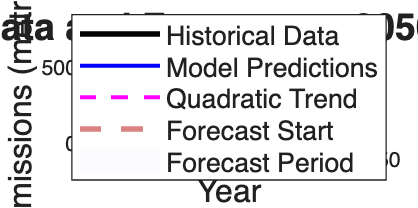


figure('Position', [100 100 1400 700]);

% Combine all actual data (only training now, since we're forecasting from 2024)
allActualTime = trainData.Year;
allActualTotal = trainData.Total;

% Combine all predictions (train + future)
allPredictedTime = [trainData.Year; futureDates];
allPredictedTotal = [yPredicted_train; futurePredictions];

% Combine all trend data
futureTrend_original = exp(futureTrendLog) - 1;
allTrendTime = [trainData.Year; futureDates];
allTrend = [exp(trendQuadratic) - 1; futureTrend_original];

% Plot historical actual data
plot(allActualTime, allActualTotal, 'k-', 'LineWidth', 2, 'DisplayName', 'Historical Data');
hold on;

% Plot all predictions (historical + future)
plot(allPredictedTime, allPredictedTotal, 'b-', 'LineWidth', 1.5, 'DisplayName', 'Model Predictions');

% Plot quadratic trend
plot(allTrendTime, allTrend, 'm--', 'LineWidth', 1.5, 'DisplayName', 'Quadratic Trend');

% Mark train/forecast split
xline(datetime(2024, 1, 1), '--', 'Color', [0.8 0.3 0.3], 'LineWidth', 2, ...
    'DisplayName', 'Forecast Start', 'Alpha', 0.7);

% Add shaded region for forecast period
forecastStart = datetime(2024, 1, 1);
forecastEnd = datetime(2050, 12, 31);
ylims = ylim;
fill([forecastStart forecastEnd forecastEnd forecastStart], ...
     [ylims(1) ylims(1) ylims(2) ylims(2)], ...
     [0.9 0.9 1], 'FaceAlpha', 0.2, 'EdgeColor', 'none', ...
     'DisplayName', 'Forecast Period');

xlabel('Year', 'FontSize', 12);
ylabel('CO₂ Emissions (metric tons)', 'FontSize', 12);
title('France CO₂ Emissions: Historical Data and Forecast to 2050 (ARIMA(5,0,5) with Quadratic Trend)', 'FontSize', 14);
legend('Location', 'best', 'FontSize', 10);
grid on;
hold off;

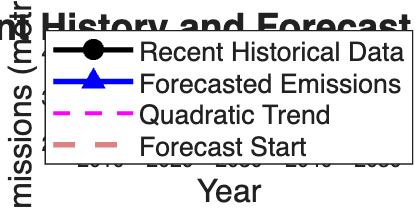


%% SECTION 7 — Zoom in on forecast period
figure('Position', [100 100 1200 600]);

% Show last 10 years of actual + all forecast
recentStartYear = lastYear - 10;
recentIdx = allActualTime >= datetime(recentStartYear, 1, 1);

% Plot recent actual data
recentActualTime = allActualTime(recentIdx);
recentActualTotal = allActualTotal(recentIdx);
plot(recentActualTime, recentActualTotal, 'ko-', 'LineWidth', 2, 'MarkerSize', 6, ...
    'MarkerFaceColor', 'k', 'DisplayName', 'Recent Historical Data');
hold on;

% Plot forecast
plot(futureDates, futurePredictions, 'b^-', 'LineWidth', 2, 'MarkerSize', 5, ...
    'MarkerFaceColor', 'b', 'DisplayName', 'Forecasted Emissions');

% Plot trend for this period
recentTrendIdx = allTrendTime >= datetime(recentStartYear, 1, 1);
plot(allTrendTime(recentTrendIdx), allTrend(recentTrendIdx), 'm--', 'LineWidth', 1.5, ...
    'DisplayName', 'Quadratic Trend');

% Mark forecast start
xline(datetime(lastYear+1, 1, 1), '--', 'Color', [0.8 0.3 0.3], 'LineWidth', 2, ...
    'DisplayName', 'Forecast Start');

xlabel('Year', 'FontSize', 12);
ylabel('CO₂ Emissions (metric tons)', 'FontSize', 12);
title(sprintf('Detailed View: Recent History and Forecast to 2050 (ARIMA(5,0,5))'), 'FontSize', 14);
legend('Location', 'best', 'FontSize', 10);
grid on;
hold off;


%% SECTION 8 — Summary statistics
fprintf('\n===== FORECAST SUMMARY =====\n');


===== FORECAST SUMMARY =====


fprintf('Model: ARIMA(5,0,5) with Quadratic Detrending\n');

Model: ARIMA(5,0,5) with Quadratic Detrending


fprintf('Training period: 1810 to 2023\n');

Training period: 1810 to 2023


fprintf('Last historical year: 2023 (Emissions: %.2f)\n', trainData.Total(end));

Last historical year: 2023 (Emissions: 333.38)


fprintf('Forecast period: 2024 to 2050\n');

Forecast period: 2024 to 2050


fprintf('\nKey forecast values:\n');


Key forecast values:


fprintf('  2024: %.2f\n', futurePredictions(futureYears == 2024));

  2024: 316.93


fprintf('  2025: %.2f\n', futurePredictions(futureYears == 2025));

  2025: 314.69


fprintf('  2030: %.2f\n', futurePredictions(futureYears == 2030));

  2030: 299.88


fprintf('  2040: %.2f\n', futurePredictions(futureYears == 2040));

  2040: 265.41


fprintf('  2050: %.2f\n', futurePredictions(end));

  2050: 227.53


fprintf('\nProjected change from 2023 to 2050: %.2f (%.1f%%)\n', ...
    futurePredictions(end) - trainData.Total(end), ...
    100 * (futurePredictions(end) - trainData.Total(end)) / trainData.Total(end));


Projected change from 2023 to 2050: -105.86 (-31.8%)



%% SECTION 9 — Save forecast results
save('Forecast_to_2050.mat', 'forecastTable', 'futurePredictions', 'futureDates', ...
     'futureYears', 'bestModel', 'quadraticModel');
fprintf('\n✅ Forecast results saved to Forecast_to_2050.mat\n');


✅ Forecast results saved to Forecast_to_2050.mat



% Export to CSV
writetable(forecastTable, 'Forecast_to_2050.csv');
fprintf('✅ Forecast table exported to Forecast_to_2050.csv\n');

✅ Forecast table exported to Forecast_to_2050.csv
